# DAFx 2022 Tutorial: Sinusoidal Modeling

## Preliminaries

Run `prelim` script to perform preliminary tasks. Add base folder and all subfolders to the Matlab path. Load definition of colors for plotting.

prelim;

### Live Script Flags

These flags control the general behavior of the script, such as enabling/disabling automatically playing the sounds.

playsndflag = true;

## Load Sound File

[sndfile,fpath] = uigetfile('audio/*.wav');

Get file path, name, and extension

[~,fname,fext] = fileparts(sndfile);

Clean up sound file name

sndname = strrep(fname,'_',' ');

### Read Sound File

[wav,fs] = audioread(sndfile);

## Sinusoidal Analysis Parameters

### Spectral AnalysisAnalysis Window

winflag = 6;

#### Causality of First Window

The text flag `CAUSALFLAG` controls the causality of the first window. The option `CAUSALFLAG = "CAUSAL" `uses a ***causal*** first analysis window, placing it totally *inside* the waveform to be analyzed. The option `CAUSALFLAG = "NON" `uses a ***non-causal*** first analysis window`,` placing its center at the first sample of the waveform to be analyzed. Finally, the option `CAUSALFLAG = "ANTI"` uses an ***anti-causal*** first analysis window, placing it totally *outside* the waveform to be analyzed.

causalflag = "non";

#### Normalize Analysis Window

normflag = true;

#### Zero-Phase Window

zphflag = true;

### Parameter Estimation

paramestflag = "lin";

### Maximum Number of Spectral Peaks to Retrieve from Analysis

maxnpeak = 150;

#### Return `MAXNPEAK` Frequency Bins

npeakflag = true;

#### Partial Tracking

The logical flag `PTRACKFLAG `controls partial tracking`.` Set `PTRACKFLAG = TRUE `to enable partial tracking and `PTRACKFLAG = FALSE` otherwise.

ptrackflag = true;

The text flag `PTRACKALGFLAG `selects the partial tracking algorithm. Currently, only *peak-to-peak* partial tracking is implemented`.`

ptrackalgflag = "p2p";

#### Peak Selection

peakselflag = true;

#### Peak Shape Threshold

The ***peak shape*** is a measure of the normalized dot product between the selected spectral peak and the DFT of the window modulated by a stationary sinusoid with the frequency of the peak. The *peak shape threshold* is normalized between 0 and 1. The recommended value is `SHAPETHRES = 0.8`. Set `SHAPETHRES = 0` to ignore it.

shapethres = 0.8;

#### Peak Range Threshold

The ***peak range*** is a measure of the *amplitude dynamic range* of each spectral peak. It measures the average of the difference between the peak value and the first trough to the right and to the left. The *peak range threshold* is set in dB power. The recommended value is `RANGETHRES = 20` dB. Set `RANGETHRES = Inf` to ignore it.

rangethres = 17;

#### Peak Relative Energy Threshold

The ***peak relative energy*** is a measure of the maximum of each spectral peak relative to the maximum level in the spectral frame. The *peak relative threshold* is set in dB power. The recommended value is `RELTHRES = -90` dB. Set `RELTHRES = -Inf` to ignore it.

relthres = -90;

#### Peak Absolute Energy Threshold

The peak absolute energy is a measure of the maximum of each peak relative to 0 dB power. The peak absolute energy threshold is set in dB power. The recommended value is `ABSTHRES = -100` dB. Set `ABSTHRES = -Inf` to ignore it.

absthres = -100;

#### Spectral Analysis Parameters

These parameters further specify the spectral analysis.

#### Frame Length Multiplier

The frame length multiplier sets the frame length as `M = n*T0`, where `n` is the number of fundamental periods `T0`. The recommended value depends on peak selection. Set `NT0 = 6` when `PEAKSEL = TRUE` and `NT0 = 4` otherwise.

nT0 =  6;

#### Oversampling Factor

The oversampling factor sets the size of the FFT. The recommended value depends on peak selection. Set `OSFAC = 4` when `PEAKSEL = TRUE` and `OSFAC = 2` otherwise.

osfac = 4;

#### Window Overlap

The windows overlap controls the hop size relative to the frame size. The window overlap varies between 0 and 1 in percentage. The recommended value depends on peak selection. Set `OVERLAP = 0.75` when `PEAKSEL = TRUE` and `OVERLAP = 0.5` otherwise.

overlap = 0.55;

### Track Duration Selection

Set `TRACKDURFLAG = TRUE` to further select spectral peaks after partial tracking according to the duration of track segments.

trackdurflag = true;

#### Duration Threshold

Minimum partial track segment duration in miliseconds.

durthres = 150;

#### Connect Over

Gap threshold to connect over in miliseconds.

gapthres = 50;

### Harmonic Selection

harmselflag = false;
tvarf0flag = false;

#### Maximum Harmonic Deviation

The variable `MAX_HARM_DEV` controls the maximum harmonic deviation in cents between the *harmonic template* and the partials.

max_harm_dev = 200;

#### Harmonic Threshold

The variable `HARM_THRESH` sets the harmonic threshold to consider a partial as harmonic or not. Lower values relax the constraint.

harm_thresh = 0.7;

#### Harmonic Partial Flag

harmpartflag = "count";

## Sinusoidal Resynthesis Parameters

### Resynthesis Algorithm

synthflag = "PI";

Set `DISPFLAG = TRUE` to display real-time resynthesis information.

dispflag = false;

### Variable Parameters

Calculate time-varying fundamental frequency `f0`

f0 = swipep_mod(wav,fs,[75 500],1000/fs,[],1/20,0.5,0.2);

Average of `f0`

ref0 = tools.f0.reference_f0(f0);

Frame size $M=nT_0=n\frac{f_s}{f_0}$.

framelen = tools.dsp.framesize(f0,fs,nT0);

Hop size $H$.

hop = tools.dsp.hopsize(framelen,overlap);

Size of the FFT $N$.

nfft = tools.dsp.fftsize(framelen,osfac);

Frequency difference for peak matching in Hz

freqdiff = tools.dsp.freq_diff4peak_matching(ref0);

## Sinusoidal Analysis

[amplitude,frequency,phase,center_frame,npartial,nframe,nchannel,nsample,dc] = sinusoidal_analysis(wav,framelen,hop,nfft,fs,...
    winflag,causalflag,normflag,zphflag,paramestflag,maxnpeak,npeakflag,...
    ptrackflag,ptrackalgflag,freqdiff,...
    peakselflag,shapethres,rangethres,relthres,absthres,...
    trackdurflag,durthres,gapthres,...
    harmselflag,ref0,tvarf0flag,max_harm_dev,harm_thresh,harmpartflag);

Sinusoidal Analysis
Peak selection
Partial tracking
Minimum duration


## Figure Data and Parameters

Make spectra for figures and set parameters for plots.

### Plot Parameters

Flag for log magnitude spectrum of plot.

logplotflag = "dbp";

Flag to select only positive frequencies or full frequency range with negative and positive frequencies.

posfreqplotflag = true;

Choose frame and audio channel.

iplot = floor(nframe/2);
ichannel = 1;

Replace `-Inf` in spectrogram

nanflag = false;

### Spectrogram of Original Sound

Size of FFT for spectrogram

nfft_specgram = 2048;
[fftframe_wav,cfr_specgram,nsample,nframe,nchannel,dc] = tools.stft.stft(wav,framelen,hop,nfft_specgram,winflag,causalflag,normflag,zphflag);

### Spectrogram

#### Amplitude

specgram = tools.fft2.fft2log_mag_spec(fftframe_wav,nfft_specgram,logplotflag,posfreqplotflag);

#### Time

time_specgram = cfr_specgram'/fs;

#### Frequency

if posfreqplotflag
    freq_specgram = tools.plot.mkfreq(nfft_specgram,fs)/1000;
    fmax = fs/2000;
else
    freq_specgram = tools.plot.mkfreq(nfft_specgram,fs,'full')/1000;
    fmax = fs/1000;
end

### Parameters of Plot

Maximum display frequency in $kHz$.

fmax = 5;

Maximum display amplitude in $dB$

amin = -150;

### Plot Spectrogram

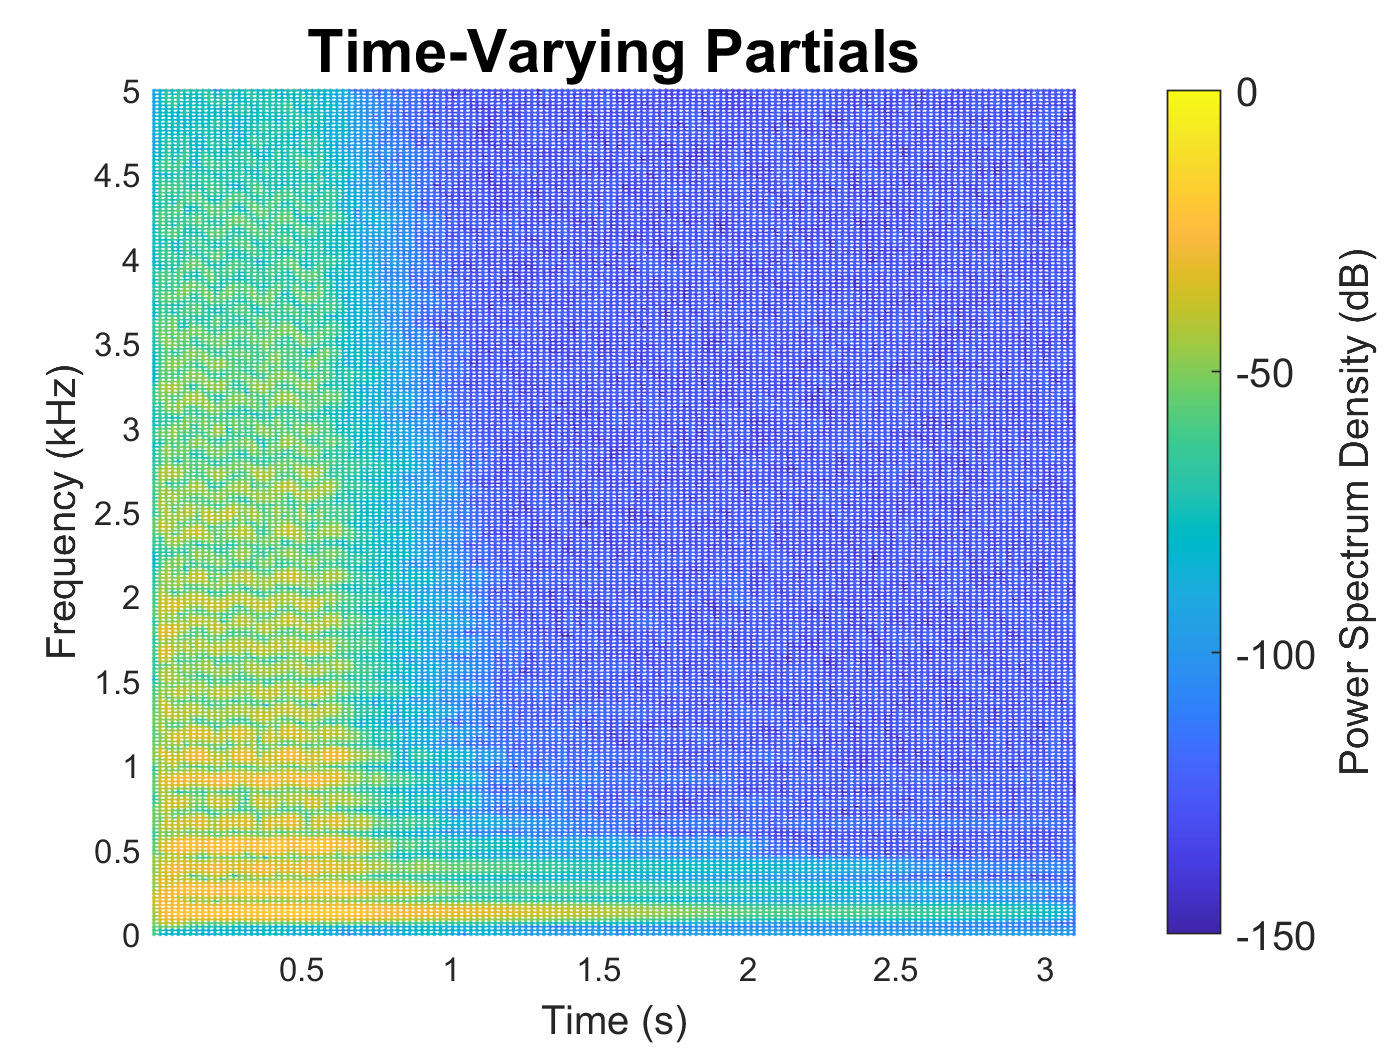

mesh(time_specgram,freq_specgram,specgram,'LineStyle',"-",'MeshStyle',"both",'LineWidth',0.5,'Marker',".","MarkerSize",4)
title('Time-Varying Partials','FontSize',18)
xlabel('Time (s)','FontSize',12)
ylabel('Frequency (kHz)','FontSize',12)
cb = colorbar;
cb.Label.String = 'Power Spectrum Density (dB)';
cb.FontSize = 12;
xlim([time_specgram(1) time_specgram(end)])
ylim([0 fmax])
view([0.5 90])
caxis([amin 0])
box("on")

### Spectro-Peakgram

#### Amplitude

specpeakgram = tools.math.lin2log(amplitude,logplotflag,nanflag);

#### Time

time_spec = repmat(center_frame/fs,[1,npartial])';

#### Frequency

freq_spec = frequency/1000;

### Plot Partial Tracking

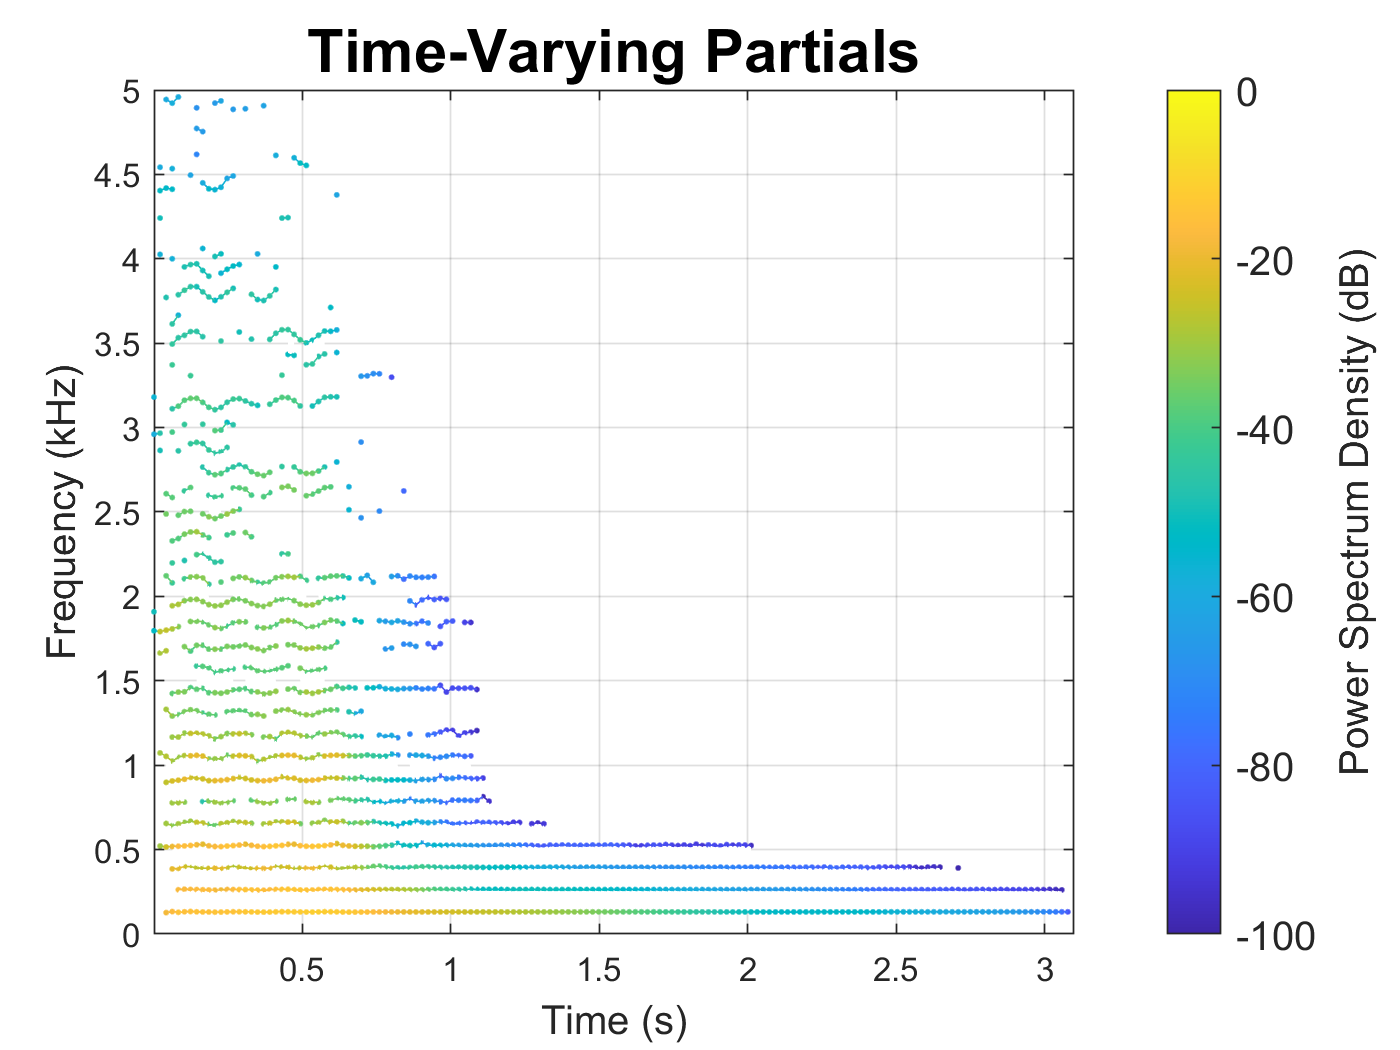

mesh(time_spec,freq_spec,specpeakgram,'LineStyle',"-",'MeshStyle',"row",'Marker',".",'MarkerSize',5)
title('Time-Varying Partials','FontSize',18)
xlabel('Time (s)','FontSize',12)
ylabel('Frequency (kHz)','FontSize',12)
cb = colorbar;
cb.Label.String = 'Power Spectrum Density (dB)';
cb.FontSize = 12;
xlim([time_spec(1) time_spec(end)])
ylim([0 max(freq_spec(:))])
% ylim([0 5])
view([0.5 90])
caxis([absthres 0])
box("on")

## Sinusoidal Resynthesis

[sinusoidal,partial,amp_partial,freq_partial,phase_partial] = sinusoidal_resynthesis(amplitude,frequency,phase,...
    framelen,hop,fs,winflag,causalflag,center_frame,npartial,nframe,nchannel,nsample,synthflag,...
    ptrackflag,ptrackalgflag,freqdiff,...
    trackdurflag,durthres,gapthres,dispflag);

Sinusoidal Resynthesis
Resynthesis by Polynomial Interpolation


### Residual from Sinusoidal Resynthesis

Calculate the residual from sinusoidal analysis as $\varepsilon(n) = w(n) - s(n)$.

residual = wav - sinusoidal;

#### Signal-to-Resynthesis Energy Ratio (SRER)

Calculate the signal-to-resynthesis energy ratio for the model as $\sqrt{\left[\frac{w\left(n\right)}{\varepsilon\left(n\right)}\right]^2}$

srer_db = tools.wav.srer(wav,residual);

## Plot Sinusoidal Model

### Figure Parameters

time_samples = tools.plot.mktime(nsample,fs);

### Plot Original vs Sinusoidal vs Residual

plot(time_samples,wav(:,ichannel),'Color',col.nb)
hold on
plot(time_samples,sinusoidal(:,ichannel),'Color',col.g)
plot(time_samples,residual(:,ichannel),'Color',col.b)
hold off
legend({'Original','SM Model','Residual'},'FontSize',12)
title(sprintf('SRER: %2.2fdB',srer_db),'FontSize',18)
xlabel('Time (s)','FontSize',12)
ylabel('Amplitude (normalized)','FontSize',12)
xlim([time_samples(1) time_samples(end)])
ylim([-1 1])

### Plot Original vs Sinusoidal

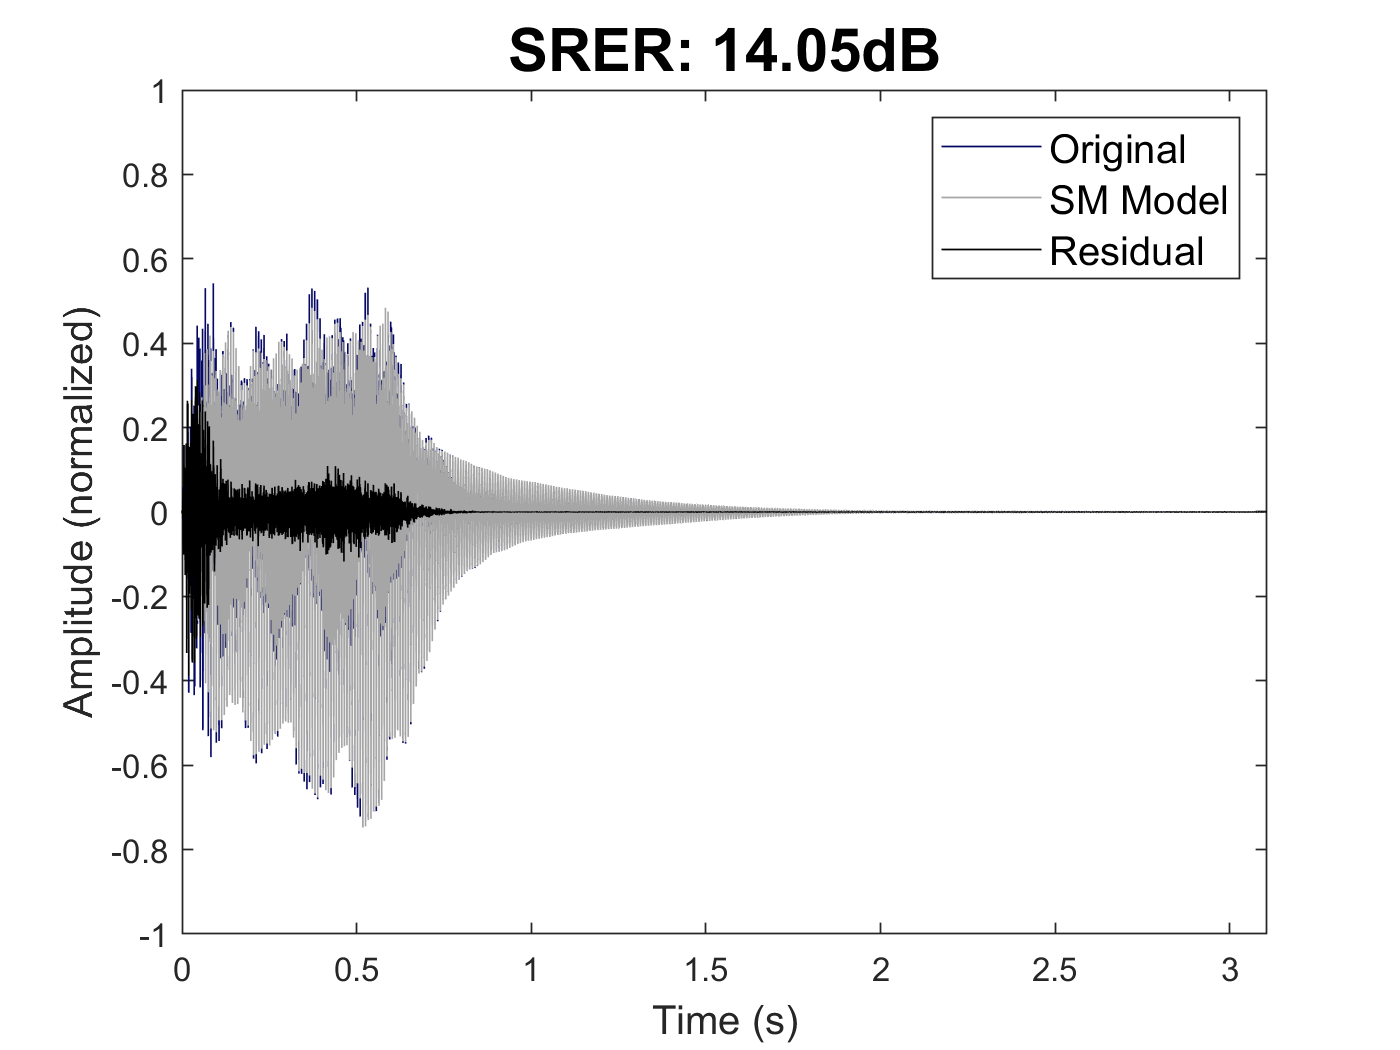

plot(time_samples,wav(:,ichannel),'Color',col.b)
hold on
plot(time_samples,sinusoidal(:,ichannel),'Color',col.g)

hold off
legend({'Original','SM Model'},'FontSize',12)
title('Waveforms: Original vs SM Model','FontSize',18)
xlabel('Time (s)','FontSize',12)
ylabel('Amplitude (normalized)','FontSize',12)
xlim([time_samples(1) time_samples(end)])
ylim([-1 1])

### Plot Original vs Residual

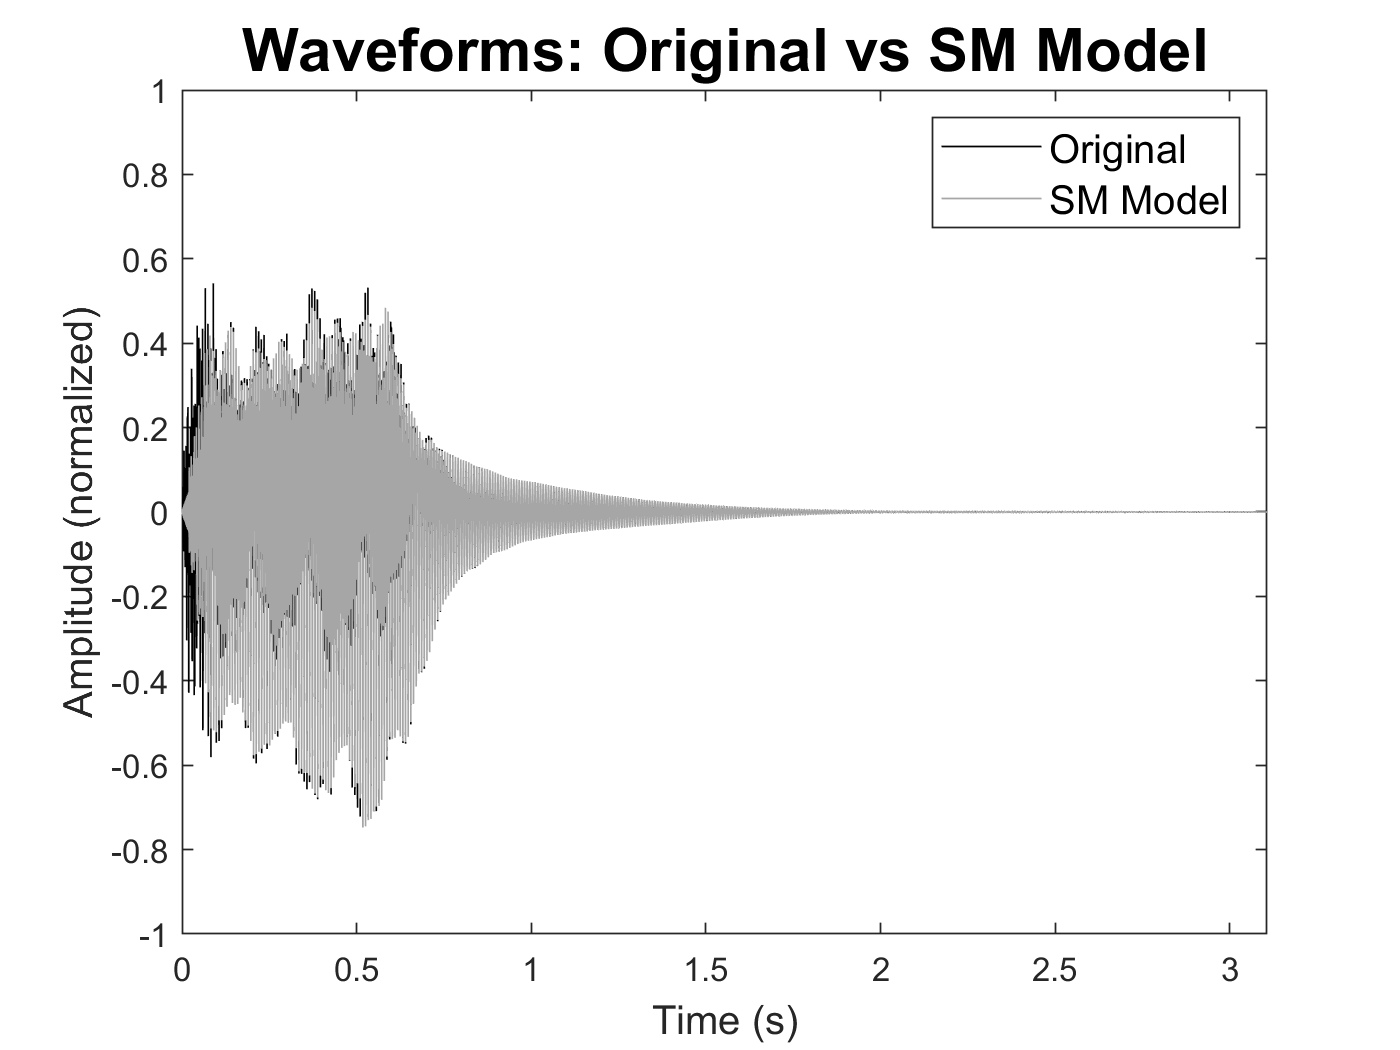

plot(time_samples,wav(:,ichannel),'Color',col.g)
hold on
plot(time_samples,residual(:,ichannel),'Color',col.b)
hold off
legend({'Original','Residual'},'FontSize',12)

title('Waveforms: Original vs Residual','FontSize',18)
xlabel('Time (s)','FontSize',12)
ylabel('Amplitude (normalized)','FontSize',12)
xlim([time_samples(1) time_samples(end)])
ylim([-1 1])

### Plot Sinusoidal vs Residual

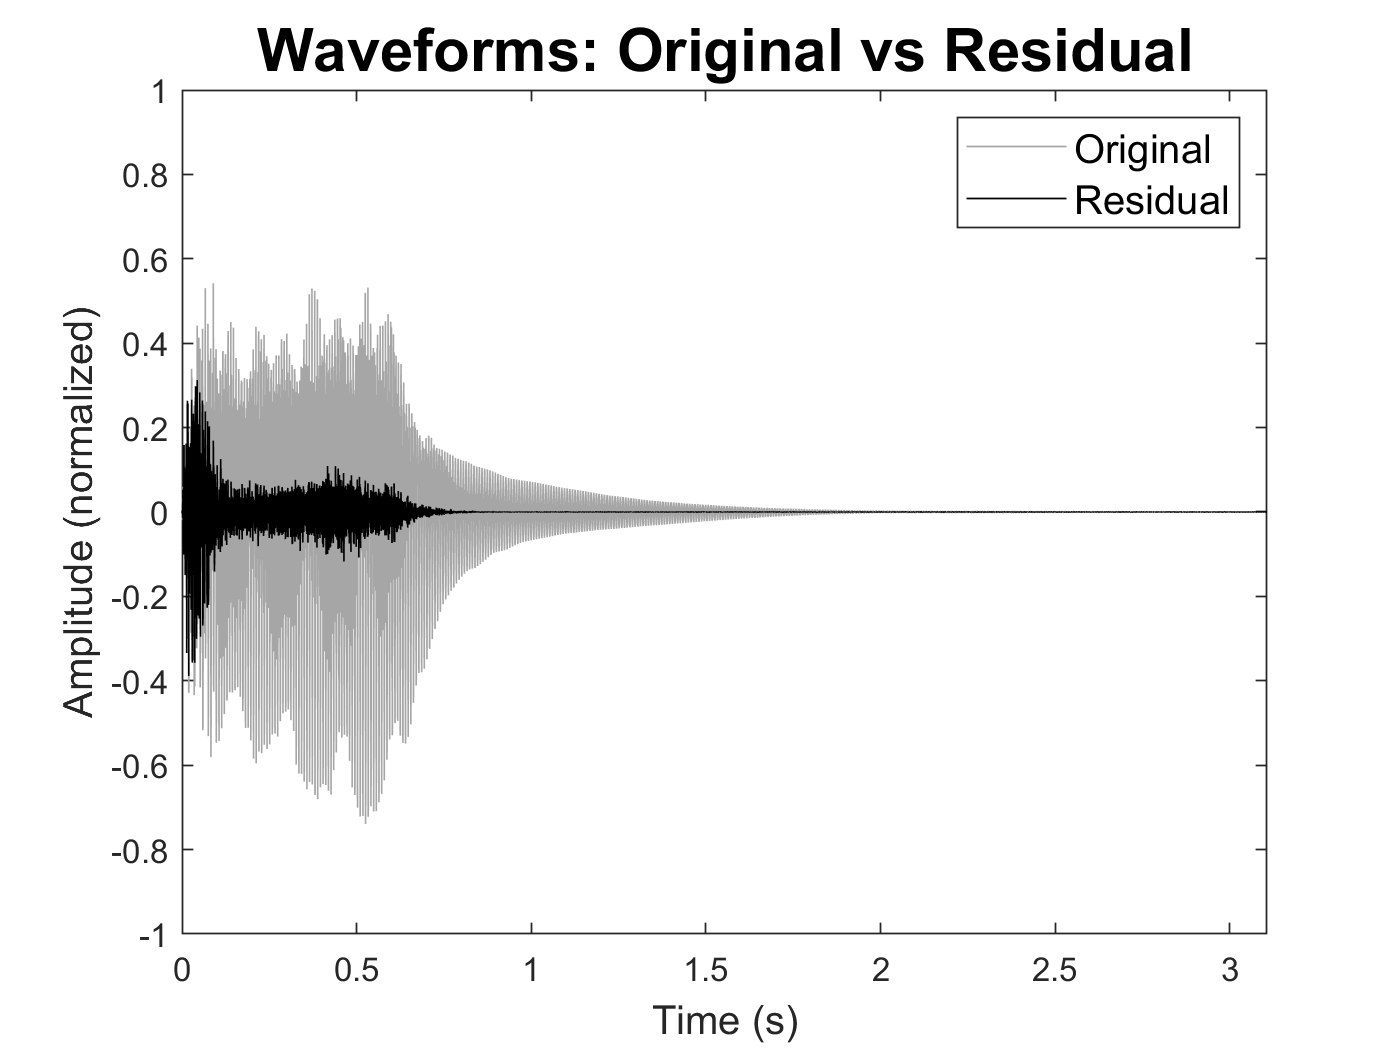

plot(time_samples,sinusoidal(:,ichannel),'Color',col.g)
hold on
plot(time_samples,residual(:,ichannel),'Color',col.b)
hold off
legend({'SM Model','Residual'},'FontSize',12)
title('Waveforms: SM Model vs Residual','FontSize',18)
xlabel('Time (s)','FontSize',12)

ylabel('Amplitude (normalized)','FontSize',12)
xlim([time_samples(1) time_samples(end)])
ylim([-1 1])

## Play Original Sound

if playsndflag
    sound(wav,fs)
    pause(nsample/fs)
end

## Play Sinusoidal model

if playsndflag
    sound(sinusoidal,fs)
    pause(nsample/fs)
end

## Play Modeling Residual

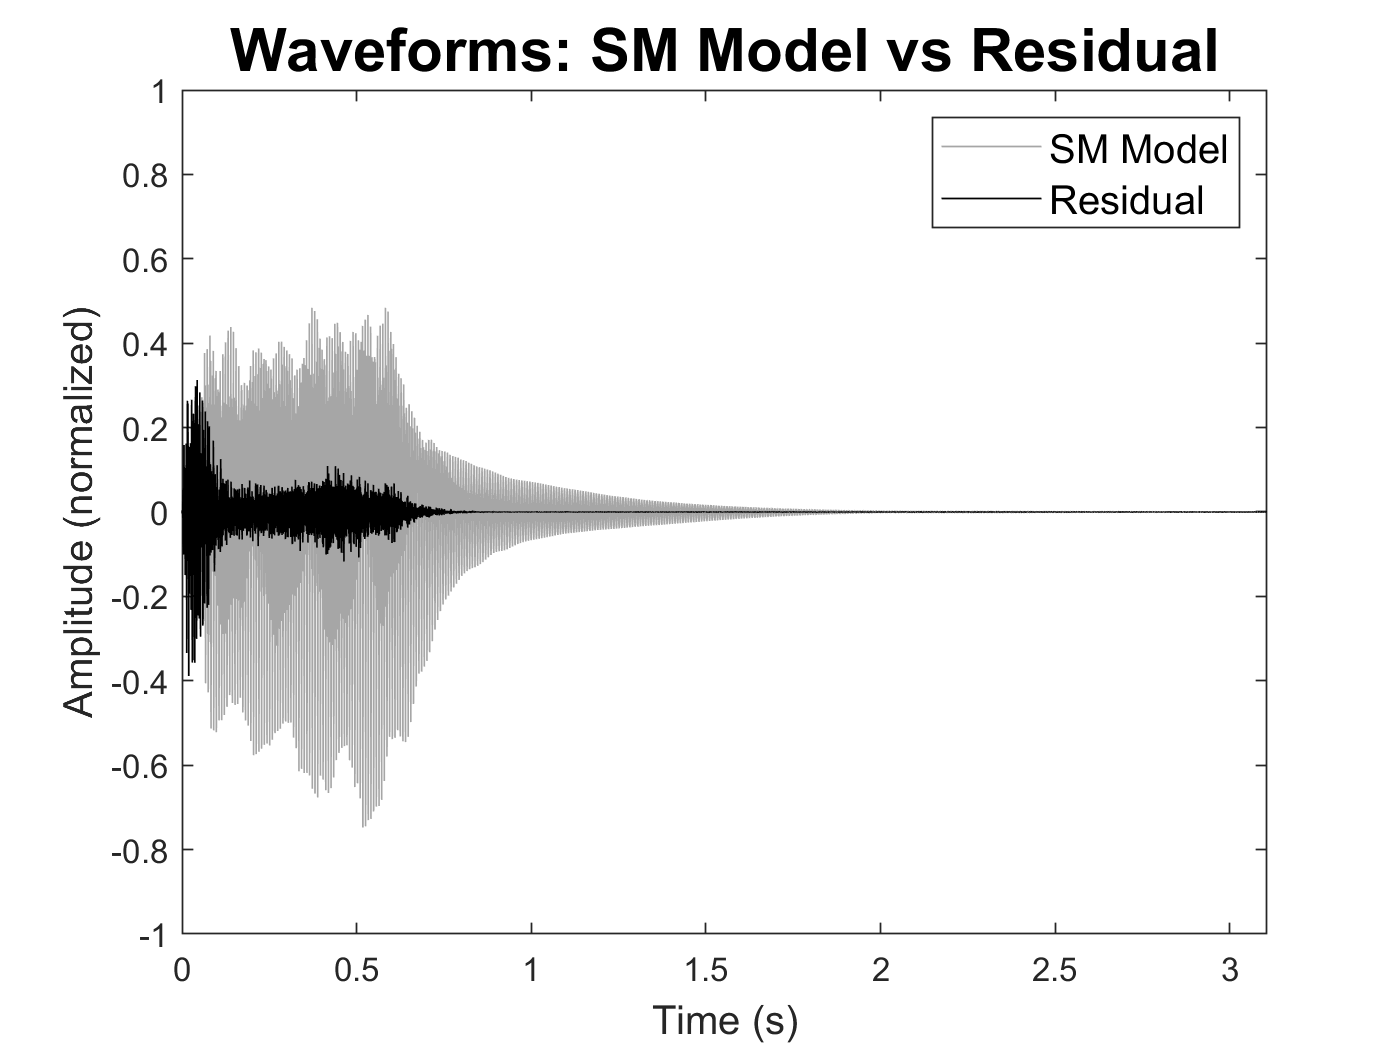

if playsndflag

    sound(residual,fs)
    pause(nsample/fs)
end

Normalize modeling residual and play.

if playsndflag
    sound(tools.wav.normdb(residual,-16,'rms'),fs)
end

## Acknowledgements

This project has received funding from the European Union’s Horizon 2020 research and innovation programme under the Marie Sklodowska-Curie grant agreement No 831852 (MORPH)